# **LAB4 - REGOLAZIONE DELLA TRASCRIZIONE**

*Compute the information content I for the 21 positions of the site. Since Fis binds to DNA on both strands, consider both the sequences and their reverse complement. Which positions have I>0.8 bits?*

Dalla matrice contenente i siti di legame allinaeati `A `nel file `alignment.mat (60x21, `quindi 60 sequenze di 21 basi allineate)

load("alignment.mat"); A

A = 60×21 char array
    'tttgccgattatttacgcaaa'
    'agtgactaaaatttacactca'
    'gtggtgcgataattactcata'
    'attgcatttaaaatgagcgtg'
    'attggtcaaagtttggccttt'
    'atgagttaagaaatgaccata'
    'acaactcaaaaactgaacaac'
    'taagtatacagatcgtgcgat'
    'aacgggcaataattgttcagc'
    'aacgctcgaaaaactggcagt'
    'accgcgcaacattcaaccaaa'
    'gatgttgaaaaagtgtgctaa'
    'cacgatgaagaaacagccgaa'
    'gtcgcataaaatgtgaccaat'
    'ggcgattaaagaataatcgtt'
    'aacggattaaaggtaaccagt'
    'tacggatgaaaattacgcaac'
    'accgaatagaaaacaaccatt'
    'attgaccacaactgatacatc'
    'aaagattaataagccatctat'
    'cccgttcaagaaatcgcccga'
    'gaagagaaaaatttgttaaaa'
    'tgagctaaaaaattcatcgat'
    'tttggatagaatataatcgat'
    'gctgcgcgataaatcgccaca'
    'tgtaatcatcatttccacaac'
    'agcggctaacaatttgccagc'
    'actggcgaagatttcgccagt'
    'aaaggtcattaactgcccaat'
    'tccggttaaggaatgtacaat'
    'ggggatcaagatctgatcaag'
    'agcgactaaaattcttcctta'
    'gggtgtcaacaattgaccaaa'
    'tgcggtcacaatttgcactag'
    'gcggactgggatttgttcagg'

calcoliamo la sequenza complementare (sullo strando opposto)  `A2 `con la funzione `seqrcomplement ` e la aggiungiamo in coda alla matrice, così da avere tutte le sequenze da tenere in considerazione nella stessa matrice.

A2 = A;
for i=1:60
    A2 = [A2; seqrcomplement(A2(i,:))];
end

Inizializziamo la **weight matrix **come una matrice di zeri 4x21: dobbiamo infatti calcolare la frequenza di ognuna delle 4 basi per ognuna delle 21 posizioni. Costruiamo poi la weight matrix contando con `nnz `il numero di occorrenze di ogni base per colonna e dividendo per il numero di sequenze (60x2 = 120, perchè consideriamo anche le sequenze complementari che abbiamo aggiunto in coda);

wm = zeros(4,21);
for i=1:21
    wm(1,i) = nnz(A2(:,i)=='a')/120;
    wm(2,i) = nnz(A2(:,i)=='c')/120;
    wm(3,i) = nnz(A2(:,i)=='g')/120;
    wm(4,i) = nnz(A2(:,i)=='t')/120;
end
wm 

wm =     0.3750    0.2333    0.2000    0.0500    0.2583    0.2083    0.0583    0.7667    0.5750    0.4250    0.4583    0.3667    0.2250    0.0500    0.3917    0.4583    0.2250    0.0417    0.4333    0.4083    0.3250
    0.0833    0.1833    0.2333    0.0083    0.2333    0.1833    0.3917    0.0250    0.1000    0.1000    0.0417    0.1083    0.1000    0.1583    0.1583    0.1500    0.2833    0.9000    0.1333    0.1750    0.2167
    0.2167    0.1750    0.1333    0.9000    0.2833    0.1500    0.1583    0.1583    0.1000    0.1083    0.0417    0.1000    0.1000    0.0250    0.3917    0.1833    0.2333    0.0083    0.2333    0.1833    0.0833
    0.3250    0.4083    0.4333    0.0417    0.2250    0.4583    0.3917    0.0500    0.2250    0.3667    0.4583    0.4250    0.5750    0.7667    0.0583    0.2083    0.2583    0.0500    0.2000    0.2333    0.3750


La somma per colonne della weight matrix deve essere pari a uno per ogni colonna.

sum(wm,1) % sum(wm,1) somma per colonne, sum(wm,2) somma per righe

ans =     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Il conenuto informativo per ogni posizione dell'allineamento è ricavabile dall'**entropia di Shannon**


$$H\left(l\right)=-\sum_{b=1}^4 f\left(b,l\right)\cdot \log_2 \left\lbrack f\left(b,l\right)\right\rbrack$$


wm(wm==0) = 1; %Sostituiamo gli elementi nulli che nel logaritmo darebbero -Inf con 1,
               % che non contribuisce alla somma perchè = 0
H = -wm.*log2(wm);
H = sum(H,1) 

H =     1.8344    1.9063    1.8647    0.6015    1.9940    1.8466    1.7194    1.0640    1.6076    1.7349    1.4138    1.7349    1.6076    1.0640    1.7194    1.8466    1.9940    0.6015    1.8647    1.9063    1.8344


Il contenuto informativo alla posizione *l-esima *vale 


$$I\left(l\right)=2-H\left(l\right)$$


I = 2-H

I =     0.1656    0.0937    0.1353    1.3985    0.0060    0.1534    0.2806    0.9360    0.3924    0.2651    0.5862    0.2651    0.3924    0.9360    0.2806    0.1534    0.0060    1.3985    0.1353    0.0937    0.1656


Le posizione con contenuto informativo > 0.8 si ricavano con la funzione `find. `In queste posizioni il contenuto informativo è elevato, di conseguenza siamo più sicuri della base in questa posizione

find(I>0.8)

ans =      4     8    14    18


Il contenuto informativo è visualizzabile anche con la funzione stem sulle 21 basi oppure con la funzione `seqlogo (`non utilizzabile in un live script)

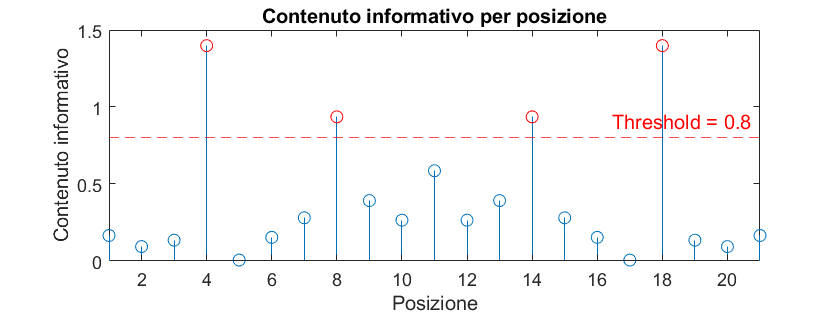

hfigure
stem(I);
yline(0.8,'r--','Threshold = 0.8');
hold on
plot(find(I>0.8),I(I>0.8),'or');
xlim([1 21]);
xlabel('Posizione');
ylabel('Contenuto informativo');
title('Contenuto informativo per posizione')

seqlogo(wm)  %--> Usare solo nella command window

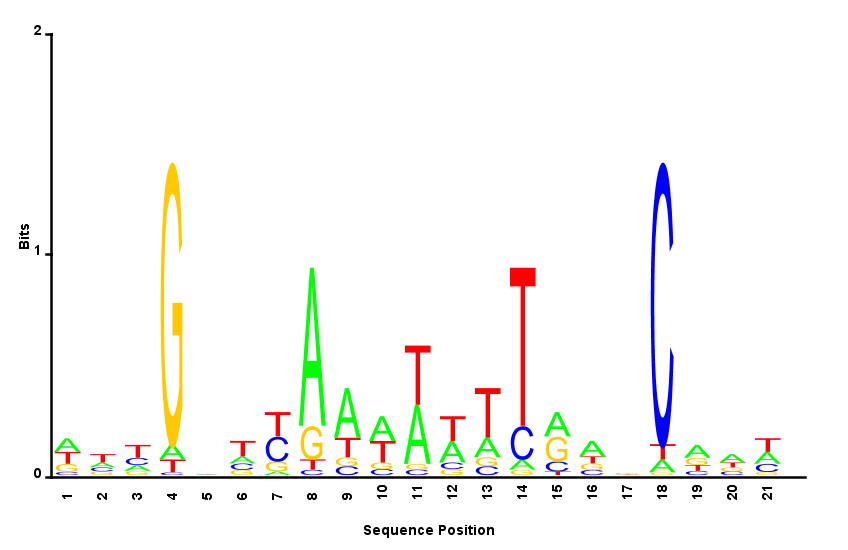

*Scan the E. coli sequence contained in K02672.fna to identify potential binding sites. Consider 400 bases upstream and 100 downstream in respect of the transcription start site (base #3395 in the file). If you use a threshold of 4.5 bits, how many positives do you find in this region? In which positions?*

Data una sequenza di basi, l'aderenza di porizioni di sequenza successive al sito di legame in A tramite un confrontata con la weight matrix. Si analizza quindi il segnale 


$$S\left(n\right)=\sum_{l=1}^L I\left(l\right)\cdot f\left(b,l\right)$$


promoter = fastaread('K02672.fna')

promoter = struct with fields:
      Header: 'gi|146964|gb|K02672.1|ECONRDA Escherichia coli ribonucleoside diphosphate reductase operon, complete sequence'
    Sequence: 'ATCCGGCGTGGGATCAGGATCGGGAGTCGGGTCTGGATCAGTGGCCGATGGCGGCGTTACTTCTTGCGATCGCAGATACCAGTCGTTGTTATCTTCCACCAGCGTGTAGTCATACGCTCCCATATTGACGTAGCCGCTGCCTGCCAGACTGAACTGCGCATTGTTTTGAAACTGCGTGGGATCAGCTGCGAAATCAACCACTTTAATGCCTGTCGATGTCGGCTCACCAATCCCTGTAATGGAGTTAACCACCACAAGTTGTGTTGCCAGCAGTATTACCGTTCATCACCAATTGATCGACTTACCGAGTCATCGCCGTTTAATTCGCTATCGAGCAGTAGCGTACCGCCGCCGGTATAATACCGTTTAACCGTCAGCGTATCGCCACGACGCCATTTGCAGGCTAACCGCACCGGACGTATTGGTCAGATTGCCATTAACCGTCACGTTGGAAAGATAAGTCAGGCTGTCAGTTTCAAGGTTGGTATTAAGCTACCTGTCAACGTCACACCATCGGTGGCATTCACCAGCGTCCCATCGCCGTTAAATAGTGAGGCATTAAGGGCGACGGAAGTATCCTGCCCGGTCAGGCGCAAAACCGTACCATCGCTGATGTCGATAGTGCCGCTGGAAATAGCATCAATTGACTGAATATCCTGATCCGCGCCAGTAACGAACGTTGCCCCATCACCAACCCACAGTGACGAAGCATAAGGAAGGATATCAGCAACATCACCTTTCAGGGTGCCTTCTTCGACACGTACCGCCGACTGCGTTGTACCGCTGGCGTCAGCTCCAGTGTACCAGCCCCCGTTTTAGTCAATGTGC

La sequenza di interesse viene inizialmente isolata come le 500 basi a cavallo del transcription starting site

promoter = promoter.Sequence(3395-400:3395+99)

promoter = 'GTCATGAATAATTTCGTTATAATATAAGGCTAAATTAACAAAATGGCTTAGCATTTAACAATAACCGAATAGAAAACAACCATTTCGCCATCAACAAGTCTCTTACATTCGCTTATATATTGACCACAACTGATACATCAGATTATGTGATGACTCGTGCTTAGATCAATTTTTGCAATCATTAGGAAAAAGATTAATAAGCCATCTATATCAATTTATCTAACCTATTATGCCCGTTCAAGAAATCGCCCGAACAGTTATTTTTAACAAATTTTTCTCTTCCCATTGACTTTCCCGGACACCTTGTCTGACCTAAGGTGCGCGAAAGGCCACTTTTTCCTTCCTGAGTTATCCACAAAGTTATGCACTTGCAAGAGGGTCATTTTCACACTATCTTGCAGTGAATCCCAAACATACCCCCTATATATAGTGTTCTAAGCAGCTTCCCGTACTACAGGTAGTCTGCATGAAACTATTGCGGAAAGAATTCCAAAAACAGG'

La lunghezza del segnale `S `è data dalla lunghezza totale della sequenza meno la lunghezza della finestra più uno.

S = zeros(1,500-21+1); % Lunghezza = Sequenza - Finestra + 1
for j=1:500-21+1
    for p=1:21
        switch promoter(j+p-1)
            case 'A'
                S(j) = S(j)+I(p)*wm(1,p);
            case 'C'
                S(j) = S(j)+I(p)*wm(2,p);
            case 'G'
                S(j) = S(j)+I(p)*wm(3,p);
            case 'T'
                S(j) = S(j)+I(p)*wm(4,p);
        end
    end
end

Possiamo plottare il segnale e confrontarlo con una soglia fissata (in questo caso **4.5 bits**). Le posizioni di probabile legame per il fattore di trascrizione sono quelle sopra soglia

hfigure
plot(S)
yline(4.5,'r--','Threshold = 4.5 bits')
find(S>4.5)

ans =     64   108   189   233


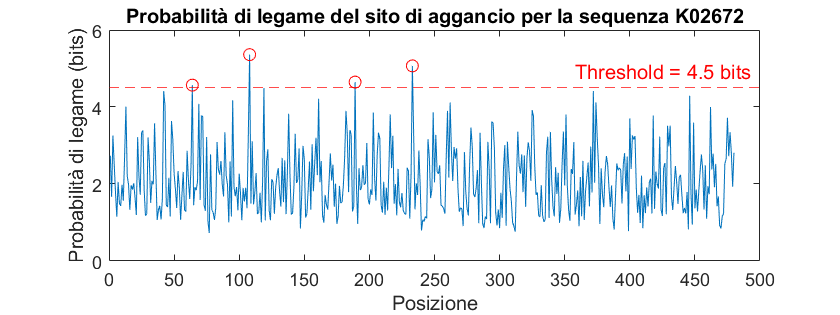

hold on
plot(find(S>4.5),S(S>4.5),'or');
xlabel('Posizione');
ylabel('Probabilità di legame (bits)');
title('Probabilità di legame del sito di aggancio per la sequenza K02672')